clc
clear
close all

% Specify the folder path containing the databases
% folderPath = '/Users/longxin/MATLAB-Drive/Q4/Radar_Project/Dataset';
% folderPath = '/Users/longxin/Downloads/all_radar';
folderPath = 'C:\Users\11362\Downloads\Dataset';

% Get a list of files in the folder
fileList = dir(fullfile(folderPath, '*.mat')); % Assuming the databases have a .mat extension

% Specify the output image folder
outputFolder = fullfile(folderPath, 'image');

% Create the output folder if it doesn't exist
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% Segment Parameters
numSegments = 5;

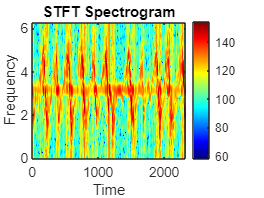

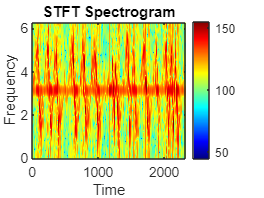

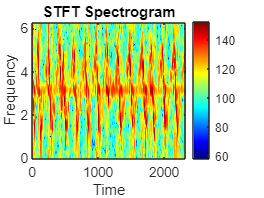

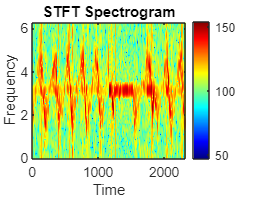

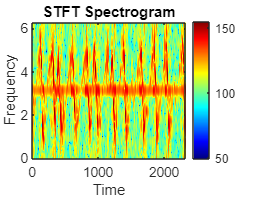

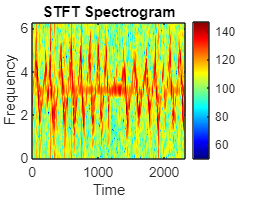

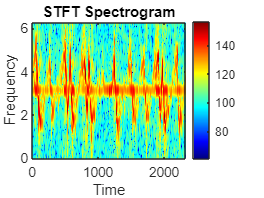

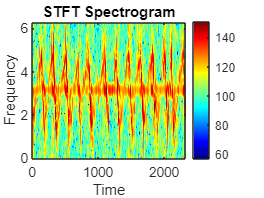

%Wait bar
h = waitbar(0, 'Processing...');

% Iterate over the files
for f = 1:numel(fileList)
% for f = 1
     % Load the databasec
    filePath = fullfile(folderPath, fileList(f).name);
    data = load(filePath);

rm  = data.hil_resha_aligned;
[II,JJ,~] = size(rm);  % Range map vector [rangebins x slowtime samples x five radars]
range_data = rm(:, :, 3);
sampling_rate = 1/61.024e-12; % from sampling interval from table from https://www.researchgate.net/publication/307627872_Multiple_statuses_of_through-wall_human_being_detection_based_on_compressed_UWB_radar_data/figures?lo=1
fast_time = II/sampling_rate; % time for one pulse
PRI = 8.2e-3; % slow_time from README
% xaxis = (1:II)*PRI;
% yaxis = (JJ/2:JJ)*fast_time;
freq_= fft(range_data,[],1);
% figure; imagesc(xaxis, yaxis, db(abs(freq_(1:240,:))))
% figure; imagesc(db(abs(freq_(1:240,:))))
center_freq = 4.3e9; % from README
% center_freq_idx = ceil(center_freq/(1/fast_time));
center_freq_idx = 120;
Rawdata = freq_(center_freq_idx,:);

% Parameters for STFT
windowLength = 32; % Length of the analysis window
overlap = 0; % Overlap between consecutive windows

% Perform STFT on the interpolated data
[spectrogramData, frequencies, times] = spectrogram(Rawdata, windowLength,...
    round(overlap*windowLength), []);

% Convert magnitude spectrogram to dB scale
spectrogramData = 20*log10(abs(spectrogramData));
spectrogramData = fftshift(spectrogramData);
% Plot the spectrogram
figure;
imagesc(times, frequencies, spectrogramData);
axis xy;
colormap('jet');
colorbar;
xlabel('Time');
ylabel('Frequency');
title('STFT Spectrogram');

% plot spectrogram
% figure
% colormap('jet'); 
% image = imagesc(TimeAxisSpectrogram,DopplerAxisSpectrogram,SpectrogramData); 
% axis xy
% ylim([-61 61]); 
% colorbar;
% clim = get(gca,'CLim');
% set(gca, 'CLim', clim(2)+[-35,0]);
% xlabel('Time[s]');
% ylabel('Doppler [Hz]')
% set(gca, 'FontSize',13)

segmentWidth = size(spectrogramData, 2) / numSegments;

% loop to create and save the image
for segmentIndex = 1:numSegments
    startCol = round(1 + (segmentIndex - 1) * segmentWidth);
    endCol = round(segmentIndex * segmentWidth);

    segmentImage = spectrogramData(:, startCol:endCol);
    
    figure;
    colormap('jet');
    imagesc(segmentImage);
    % axis xy;
    % colorbar;
    % clim = get(gca, 'CLim');
    % set(gca, 'CLim', clim(2) + [-35, 0]);
    % xlabel('Time[s]');
    % ylabel('Doppler [Hz]');
    % set(gca, 'FontSize', 13);
    axis xy;
    colormap('jet');
    % colorbar;
    % xlabel('Time');
    % ylabel('Frequency');
    % title('STFT Spectrogram');

    % Save the image to a file with the specified folder path
    [~, fileName, ~] = fileparts(fileList(f).name);
    imageName = sprintf('%s_segment%d.png',fileName,segmentIndex);
    imagePath = fullfile(outputFolder, imageName);
    saveas(gcf, imagePath);

    close;
end

% Update the progress bar
waitbar(f/numel(fileList), h);
end


close(h);

Define the class labels

classLabels_ = [];
for label = char('A':'N')
classLabels_ = [classLabels_, repmat(label, 1, 4*numSegments)];
end

classLabels = cell(size(classLabels_,2),1);
for i = 1:size(classLabels,1)
    classLabels(i) = cellstr((classLabels_(i)));
end

save([outputFolder,'/all_labels'], 'classLabels');


Convert color image to grayscale

imds = imageDatastore(outputFolder);

numberOfImages = length(imds.Files);
for k = 1 : numberOfImages
    % Get the input filename. It already has the folder prepended, so we don't need to worry about that.
    inputFileName = imds.Files{k};
    fprintf('Processing image %d of %d\n', k, numberOfImages)
    
    rgbImage = imread(inputFileName);
    [rows, columns, numberOfColorChannels] = size(rgbImage);
    
    if numberOfColorChannels == 3
        grayImage = rgb2gray(rgbImage);
        [~, filename, ext] = fileparts(inputFileName);
        grayImagePath = fullfile(folderPath, [filename '_gray' ext]);
        imwrite(grayImage, grayImagePath);
        delete(inputFileName);
        movefile(grayImagePath, inputFileName);
    end
end

Processing image 1 of 70
Processing image 2 of 70
Processing image 3 of 70
Processing image 4 of 70
Processing image 5 of 70
Processing image 6 of 70
Processing image 7 of 70
Processing image 8 of 70
Processing image 9 of 70
Processing image 10 of 70
Processing image 11 of 70
Processing image 12 of 70
Processing image 13 of 70
Processing image 14 of 70
Processing image 15 of 70
Processing image 16 of 70
Processing image 17 of 70
Processing image 18 of 70
Processing image 19 of 70
Processing image 20 of 70
Processing image 21 of 70
Processing image 22 of 70
Processing image 23 of 70
Processing image 24 of 70
Processing image 25 of 70
Processing image 26 of 70
Processing image 27 of 70
Processing image 28 of 70
Processing image 29 of 70
Processing image 30 of 70
Processing image 31 of 70
Processing image 32 of 70
Processing image 33 of 70
Processing image 34 of 70
Processing image 35 of 70
Processing image 36 of 70
Processing image 37 of 70
Processing image 38 of 70
Processing image 39 o

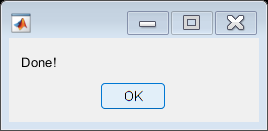


msgbox('Done!');